% This script models a state-transition process in a directed or undirected 
% network of N nodes, where each node can either be in an active or inactive 
% state (binary state). The adjacency matrix (Adj) defines the structure 
% of the network, which can be either bidirectional or directional.

% The state-transition matrix (TrMat) is calculated based on the current state 
% (STATE_PRE) and the next state (STATE_POST). Transition probabilities are 
% computed using the function GenProb, which considers the inputs from 
% neighboring nodes (F) and the probability of state transitions.

% After constructing the state-transition matrix, the eigenvalues and 
% eigenvectors of the matrix are computed to analyze the system's dynamics. 
% The stationary distribution (Prob_Vector) is derived from the eigenvector 
% corresponding to the eigenvalue equal to 1. 

% The correlation matrix (M) between different nodes is then calculated. 
% Finally, various figures are generated to visualize the results, 
% including the transition matrix, the eigenvalue distribution, 
% the stationary distribution, and the correlation matrix.


% Birectional.

% Adj = [0 1 1 0;
%        1 0 0 1;
%        1 0 0 1;
%        0 1 1 0];

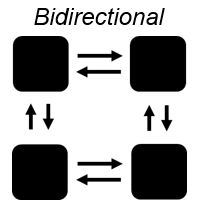

% Directional 
Adj = [0 0 0 0;
       1 0 0 0;
       1 0 0 0;
       0 1 1 0];


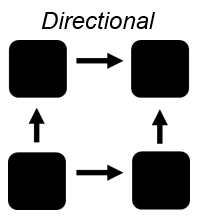

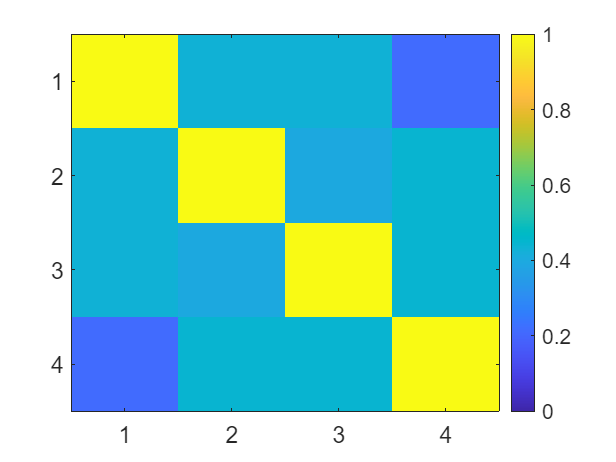


%% Caluclation of the state-transition matrix T

[N,~] = size(Adj);
 
State_Mem = zeros(2^N,N);
for s = 1:2^N
    State_Mem(s,:) = GenState(s,N);
end


Model = Model_initialize(Adj);

for s_pre = 1:2^N
    for s_post = 1:2^N
        STATE_PRE = State_Mem(s_pre,:)';
        STATE_POST = State_Mem(s_post,:)';
        F = Adj*STATE_PRE;
        Model.TrMat(s_post,s_pre) = GenProb(STATE_PRE,STATE_POST,F,Model);
    end
end

%% Calculation of eigenvalues and eigenvectors

[V,D] = eig(Model.TrMat,'vector');
D = D';

%% Derivation of stationary distribution

[~,id]  = max(abs(D));
Prob_Vector = V(:,id)/sum(V(:,id));

%% Calculation of correlation coefficients
s_bar = State_Mem'*Prob_Vector;

sigma = sqrt((State_Mem.*State_Mem)'*Prob_Vector - s_bar.^2);
Var = zeros(N);

for i = 1:N
    for j = 1:N
        Var(i,j) = (State_Mem(:,i).*State_Mem(:,j))'*Prob_Vector - s_bar(i)*s_bar(j);
    end
end
M = Var./(sigma*sigma');


fig = figure;

imagesc(M)
set(gca,'FontSize',16,'FontName','Arial')
xticks(1:N);yticks(1:N)

colorbar 
clim([0 1])

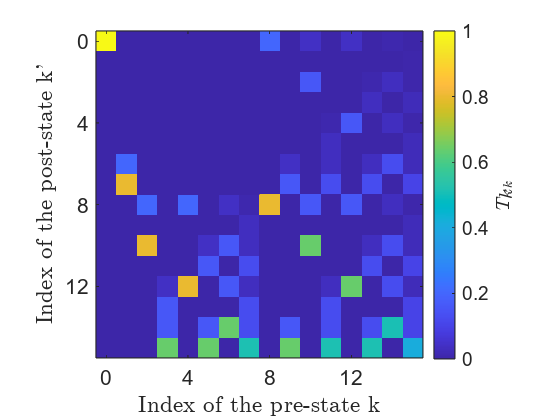

fig = figure;
s = imagesc(Model.TrMat);

pbaspect([1 1 1])
c = colorbar;
c.Label.String = '${T}_{k''k}$';
c.Label.Interpreter = 'latex';
set(gca,'FontSize',16)
set(gca,'FontName','Arial')
xticks(1:4:16)
xticklabels((1:4:16)-1)
ylabel('Index of the post-state k''','Interpreter','latex')
xlabel('Index of the pre-state k','Interpreter','latex')
clim([0 1])
yticks(1:4:16)
yticklabels((1:4:16)-1)

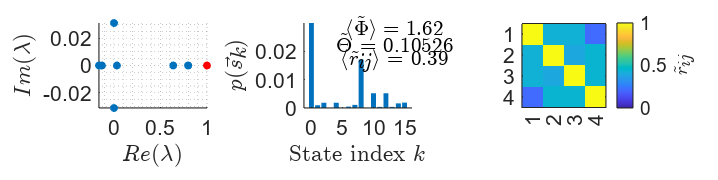

fig = figure;
fig.Position = [100 100 1000 250];
tiledlayout(1,3)
nexttile
scatter(real(D(2:end)),imag(D(2:end)),'filled')
hold on
scatter(real(D(1)),imag(D(1)),'filled','r')
xlabel('$Re(\lambda)$','Interpreter','latex');ylabel('$Im(\lambda)$','Interpreter','latex')
grid minor

set(gca,'FontSize',16)
set(gca,'FontName','Arial')
nexttile
b = bar((1:2^N)-1,Prob_Vector);
box off
b.EdgeColor = 'none';
ylim([0 3*10^-2])
xlabel('State index $k$','Interpreter','latex')
ylabel('$p(\vec{s}_k)$','Interpreter','latex')

set(gca,'FontSize',16)
set(gca,'FontName','Arial')
set(gca,'FontName','Arial')

text(13.5,0.028,['$$\langle{\tilde{\Phi}}\rangle ='  num2str(round(100*sum(State_Mem,2)'*(Prob_Vector/(1-Prob_Vector(1))))/100) '$$'],fontsize = 16,HorizontalAlignment="center",Interpreter="latex")
text(13.5,0.022,['$\tilde{\Theta}$ = '  num2str(GetDist(M(~eye(N)),20))],fontsize = 16,HorizontalAlignment="center",Interpreter="latex")
text(13.5,0.017,['$$\langle{\tilde{r}_{ij}}\rangle$$ = ' num2str(round(100*mean(M(~eye(N))))/100)],fontsize = 16,HorizontalAlignment="center",Interpreter="latex")
nexttile
imagesc(M)
c = colorbar;
c.Label.String = '$${\tilde{r}_{ij}}$$';
c.Label.Interpreter = 'latex';
pbaspect([1 1 1])
clim([0 1])
set(gca,'FontSize',16)
set(gca,'FontName','Arial')
xticks(1:4)
yticks(1:4)

function Value =  GetDist(Burst_size,bins)
    Burst_size= abs(Burst_size);
    [Prob_dist,~] = histcounts(Burst_size,0:1/bins:1,"Normalization","probability");
    Buffer = 0;
        for i  = 1:bins
            Buffer = Buffer + abs(1/bins -  Prob_dist(i));
        end

    Value = 1 - bins/(2*(bins-1))*Buffer;
end

function Model =  Model_initialize(Adj)
    N = size(Adj,1);
    Model = struct();
    Model.n_threth = 1;
    Model.sigma = 10^-3;
    Model.gamma = 0.8;
    Model.N =N;
    Model.StateSize = 2^N;
    Model.TrMat = zeros(Model.StateSize);
    Model.Adj = Adj;
end

function T =  GenProb(STATE_PRE,STATE_POST,F,Model)
    Pi = zeros(1,Model.N);
    for k = 1:Model.N
        pre = STATE_PRE(k);post = STATE_POST(k);
        PROB_TABLE = [1-Model.sigma,Model.sigma;1-Model.gamma,Model.gamma];   
        
        if F(k) >= Model.n_threth
            PROB_TABLE(1,:) = [0,1];  
        elseif (F(k) < Model.n_threth) && (F(k)~=0)
            PROB_TABLE(1,:) = [1-F(k),F(k)];
        end

        Pi(k) = PROB_TABLE(pre+1,post+1);
    end
    T = prod(Pi);
end


function State = GenState(s,N)
    State = zeros(N,1);
    STATE_STR = dec2bin(s-1,N);
    for i = 1:length(STATE_STR)
        State(N-i+1) = str2double(STATE_STR(i));
    end
end

